%Geometry with 2 hole at a random locations
%Small E for the hole
%stress being predicted with a 3rd NN

%% ===============================================================
%  Plane stress FEM parametric + TWO neural networks predicting full "u" for body forces in x and y direction separately
%  - All comments and printed messages are in English
%  - Input normalized to [-1,1], outputs normalized with z-score (per DOF)
%  - Minibatch training using dlnetwork + Adam
%  - Full inference and comparison with FEM
%  Mesh: 6 x 6 nodes (same as requested)
%  Elastic modulus E = 1, nu = 0.3
% ===============================================================

clear; close all; clc;

%% ===============================================================
% 1️⃣  PROBLEM PARAMETERS AND DOMAIN
% ===============================================================
nNodesX = 16;
nNodesY = 16;
nNodes = nNodesX * nNodesY;

inputs = 8;
B_min = 1;  B_max = 3;     % base range
H_min = 1;  H_max = 3;     % height range

dia_min = 0.1; dia_max = 0.4; % hole diameter range 
cx_min = 0.3; cx_max = 0.7; % percentages - hole centroid coordinates
cy_min = 0.3; cy_max = 0.7; % percentages - hole centroid coordinates

nSamples = 1000;           % number of geometries for training

% Material (constant)
E = 1;
E_hole = 1e-6 * E;
nu = 0.3;

% Reference unit mesh
[xGrid, yGrid] = meshgrid(linspace(0,1,nNodesX), linspace(0,1,nNodesY));
coords0 = [xGrid(:), yGrid(:)];

% DOF per node and totals
ndofNode = 2;
nDOF = nNodes * ndofNode;

fprintf('Problem: %d nodes (%dx%d) -> %d DOFs\n', nNodes, nNodesX, nNodesY, nDOF);

Problem: 256 nodes (16x16) -> 512 DOFs



tic
%% ===============================================================
% 2️⃣  DATASET CREATION (FEM) - body force applied to entire plate
%     Base (bottom, y==0) is fixed a priori in dataset and training
% ===============================================================
% Body force per unit volume (fx, fy)
bodyForcex = [1; 0];
bodyForcey = [0; 1];

% Preallocate geometry matrix and outputs (outputs = full displacement vector u)
Xdata = zeros(inputs, nSamples);  % [B; H; dia; cx; cy; dia2; cx2; cy2]
Uall1 = zeros(nDOF,nSamples);
Uall2 = zeros(nDOF,nSamples); % each column is full displacement vector for that sample

fprintf('Generating FEM dataset (%d samples) with base fixed (y==0)...\n', nSamples);

Generating FEM dataset (1000 samples) with base fixed (y==0)...



count = 0;
j = 1;
NodeStress = zeros(3*nNodes, nSamples);

for i = 1:nSamples
    % random geometric parameters
    % B = B_min + (B_max - B_min) * rand();
    % H = H_min + (H_max - H_min) * rand();
    % dia1 = dia_min + (dia_max - dia_min) * rand();
    % cx1 = (cx_min + (cx_max - cx_min) * rand())*B;
    % cy1 = (cy_min + (cy_max - cy_min) * rand())*H;
    %
    % dia2 = dia_min + (dia_max - dia_min) * rand();
    % cx2 = (cx_min + (cx_max - cx_min) * rand())*B;
    % cy2 = (cy_min + (cy_max - cy_min) * rand())*H;

    margin = 0.2; %for distance between the hole and plate boundary

    % while cx1 - dia1/2 <= margin || cx1 + dia1/2 + margin >= B || cy1 - dia1/2 <= margin || cy1 + dia1/2 + margin >= H || cx2 - dia2/2 <= margin || cx2 + dia2/2 + margin >= B || cy2 - dia2/2 <= margin || cy2 + dia2/2 + margin >= H
    %     % while cx2 - dia2/2 >= cx1 - dia1/2 || cx2 - dia2/2 <= cx1 + dia1/2 || cx2 + dia2/2 >= cx1 - dia1/2 || cx2 + dia2/2 <= cx1 + dia1/2 ||  cy2 - dia2/2 >= cy1 - dia2/2 || cy2 - dia2/2 <= cy1 + dia1/2 ||  cy2 + dia2/2 >= cy1 - dia2/2 || cy2 + dia2/2 <= cy1 + dia1/2
    %
    %     B   = B_min  + (B_max  - B_min)  * rand();
    %     H   = H_min  + (H_max  - H_min)  * rand();
    %     dia1 = dia_min + (dia_max - dia_min) * rand();
    %     cx1 = (cx_min + (cx_max - cx_min) * rand())*B;
    %     cy1 = (cy_min + (cy_max - cy_min) * rand())*H;
    %     dia2 = dia_min + (dia_max - dia_min) * rand();
    %     cx2 = (cx_min + (cx_max - cx_min) * rand())*B;
    %     cy2 = (cy_min + (cy_max - cy_min) * rand())*H;
    %
    %     count = count + 1;
    % end

    B   = B_min  + (B_max  - B_min)  * rand();
    H   = H_min  + (H_max  - H_min)  * rand();

    while true

        % Generate random geometry
        dia1 = dia_min + (dia_max - dia_min) * rand();
        cx1 = (cx_min + (cx_max - cx_min) * rand()) * B;
        cy1 = (cy_min + (cy_max - cy_min) * rand()) * H;

        dia2 = dia_min + (dia_max - dia_min) * rand();
        cx2 = (cx_min + (cx_max - cx_min) * rand()) * B;
        cy2 = (cy_min + (cy_max - cy_min) * rand()) * H;

        % -------------------------------
        % 1️⃣ Boundary check
        % -------------------------------
        boundaryViolation = ...
            (cx1 - dia1/2 <= margin) || (cx1 + dia1/2 + margin >= B) || ...
            (cy1 - dia1/2 <= margin) || (cy1 + dia1/2 + margin >= H) || ...
            (cx2 - dia2/2 <= margin) || (cx2 + dia2/2 + margin >= B) || ...
            (cy2 - dia2/2 <= margin) || (cy2 + dia2/2 + margin >= H);

        % -------------------------------
        % 2️⃣ Overlap check
        % -------------------------------
        dist_centers = sqrt((cx1 - cx2)^2 + (cy1 - cy2)^2);
        overlap = dist_centers < (dia1 + dia2)/2;

        % -------------------------------
        % 3️⃣ Accept geometry only if valid
        % -------------------------------
        if ~(boundaryViolation || overlap)
            break;  % ✅ exit loop if geometry is valid
        end

        count = count + 1;
    end

    Xdata(:,i) = [B; H; dia1; cx1; cy1; dia2; cx2; cy2];

    % physical coordinates scaled
    coords = [coords0(:,1)*B, coords0(:,2)*H];

    % build FEM stiffness and force
    [K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, E_hole, nu, bodyForcex, cx1, cy1, dia1, cx2, cy2, dia2);
    [K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, E_hole, nu, bodyForcey, cx1, cy1, dia1, cx2, cy2, dia2);

    % identify base nodes (y == 0) -> fixed
    tol = 1e-12;
    baseNodes = find(abs(coords(:,2) - 0) < tol); % bottom side, coords(i,2) → y-coordinate of node i
    fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);
    
    % % identify hole-interior nodes (disconnected from mesh)
    % dist = sqrt((coords(:,1)-cx).^2 + (coords(:,2)-cy).^2);
    % holeNodes = find(dist < dia/2);
    % 
    % % combine base nodes & hole nodes
    % fixedNodes = union(baseNodes, holeNodes);
    % fixedDOFs = reshape([(fixedNodes-1)'*ndofNode + 1 ; (fixedNodes-1)'*ndofNode + 2], [], 1);

    % free DOFs
    allDOFs = (1:nDOF)';
    freeDOFs = setdiff(allDOFs, fixedDOFs);

    % Solve for displacements: u(free) = K_ff \ F_f
    u1 = zeros(nDOF,1);
    u1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);

    u2 = zeros(nDOF,1);
    u2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);

    % Uall(:,i) = u;
    Uall1(:,i) = u1;
    Uall2(:,i) = u2;

    utot = u1 + u2;

    [nodestress] = getNodalStresses(coords, nNodesX, nNodesY, E, E_hole, nu, utot, cx1, cy1, dia1, cx2, cy2, dia2);
    nodestress_vec = reshape(nodestress', [], 1); %[] - automatically calculates the number of rows; 1 - col
    % OR: nodestress(:) depending on your ordering
    NodeStress(:,i) = nodestress_vec;
end

disp(NodeStress);

    5.6738    5.9451    6.9337    3.5600    2.6051    6.3916    4.6921    3.6249    3.5292    6.3259    3.1926    2.7838    5.6708    4.5577    1.8178    6.1223    4.1378    2.3376    1.9784    2.9309    1.6596    3.5788    2.0181    5.4297    4.9826    6.1183    1.7971    2.2954    3.0948    3.4508    5.6949    2.9035    2.1486    3.7522    2.5859    3.6164    6.0336    2.7872    4.8819    2.8993    6.2574    4.0948    2.0734    3.9855    4.3550    3.2115    7.7183    6.7169    6.3009    2.9379    2.4086    2.8512    2.2775    8.8634    2.9269    1.7344    3.8511    4.9627    2.1505    5.9934    1.7563    3.1716    6.7055    4.2149    3.9279    1.9543    2.4069    5.8823    5.3525    5.0326    5.4648    4.9801    2.2061    6.7351    2.0950    3.4591    5.1817    5.9733    4.8445    2.0379    3.9072    6.0957    4.4998    3.7442    1.7942    6.8228    2.4434    3.1524    2.3153    5.2591    1.8932    3.4303    1.9891    6.0921    3.0554    5.1539    2.6416    5.9380    5.1342    1.6069

fprintf('Wrong geometries produced %d\n times.', count);

Wrong geometries produced 470
 times.


Ux_energy = norm(Uall2(1:2:end,:),'fro');
Uy_energy = norm(Uall2(2:2:end,:),'fro');
fprintf('Energy ratio Uy/Ux = %.3e\n', Uy_energy/Ux_energy);

Energy ratio Uy/Ux = 6.222e+00



disp('✅ FEM dataset generated.');

✅ FEM dataset generated.


disp('For data generation:');

For data generation:


toc

Elapsed time is 89.365124 seconds.



%% ===============================================================
% 3️⃣  DATA PREPARATION AND NORMALIZATION
%     - Input normalization to [-1,1]
%     - Output normalization: z-score per DOF
% ===============================================================
% Input normalization to [-1,1]
Bnorm   = 2*(Xdata(1,:) - B_min)  /(B_max  - B_min)  - 1;
Hnorm   = 2*(Xdata(2,:) - H_min)  /(H_max  - H_min)  - 1;
dia1norm = 2*(Xdata(3,:) - dia_min)/(dia_max - dia_min) - 1;
cx1norm  = 2*(Xdata(4,:) - (cx_min.*Xdata(1,:))) ./((cx_max.*Xdata(1,:))  - (cx_min.*Xdata(1,:))) - 1;
cy1norm  = 2*(Xdata(5,:) - cy_min.*Xdata(2,:)) ./(cy_max*Xdata(2,:)  - cy_min*Xdata(2,:)) - 1;
dia2norm = 2*(Xdata(6,:) - dia_min)/(dia_max - dia_min) - 1;
cx2norm  = 2*(Xdata(7,:) - (cx_min.*Xdata(1,:))) ./((cx_max.*Xdata(1,:))  - (cx_min.*Xdata(1,:))) - 1;
cy2norm  = 2*(Xdata(8,:) - cy_min.*Xdata(2,:)) ./(cy_max*Xdata(2,:)  - cy_min*Xdata(2,:)) - 1;

Xnorm = [Bnorm; Hnorm; dia1norm; cx1norm; cy1norm; dia2norm; cx2norm; cy2norm];

% Output normalization (z-score) per DOF (row-wise)
epsVal = 1e-8;

mu_U1 = mean(Uall1,2);
sigma_U1 = std(Uall1,0,2) + epsVal;
Uall_norm1 = (Uall1 - mu_U1) ./ sigma_U1;

mu_U2 = mean(Uall2,2);
sigma_U2 = std(Uall2,0,2) + epsVal;
Uall_norm2 = (Uall2 - mu_U2) ./ sigma_U2;

%normalization per node (row-wise)
mu_nodestress = mean(NodeStress,2);
sigma_nodestress = std(NodeStress,0,2) + epsVal;
nodestress_norm = (NodeStress - mu_nodestress) ./ sigma_nodestress;  

% Convert to single for speed (optional)
Xn = single(Xnorm);
Un1 = single(Uall_norm1);
Un2 = single(Uall_norm2);

nodestress_n = single(nodestress_norm);

% Create dlarray for input when needed; minibatches will be formed manually
dlXall = dlarray(Xn, "CB"); 

tic
%% ===============================================================
% 4️⃣  DEFINE SINGLE NETWORK (mapping 2 -> nDOF)
% ===============================================================
% Simple fully-connected network for body force x (NN1)
nOut1 = nDOF;
nOut2 = nDOF;
nOut3 = 3*nNodes;

layers1 = [
    featureInputLayer(inputs,"Normalization","none") %2 input features;
    fullyConnectedLayer(64)
    % tanhLayer
    geluLayer
    fullyConnectedLayer(64)
    % tanhLayer
    geluLayer
    fullyConnectedLayer(nOut1)
];
dlnet1 = dlnetwork(layerGraph(layers1));

% Simple fully-connected network for body force y (NN2)
layers2 = [
    featureInputLayer(inputs,"Normalization","none") %2 input features;
    fullyConnectedLayer(64)
    % tanhLayer
    geluLayer
    fullyConnectedLayer(64)
    % tanhLayer
    geluLayer
    fullyConnectedLayer(nOut2)
];
dlnet2 = dlnetwork(layerGraph(layers2));

% Simple fully-connected network for stress prediction
layers3 = [
    featureInputLayer(inputs,"Normalization","none") %2 input features;
    fullyConnectedLayer(128)
    % tanhLayer
    geluLayer
    fullyConnectedLayer(128)
    % tanhLayer
    geluLayer
    fullyConnectedLayer(nOut3)
];
dlnet3 = dlnetwork(layerGraph(layers3));

%% ===============================================================
% 5️⃣  TRAINING (minibatch) - manual loop with Adam
%% ===============================================================
numEpochs = 1000;
learnRate = 1e-3; 
miniBatchSize = 200;

avgGrad1 = [];
avgSqGrad1 = []; 
avgGrad2 = [];
avgSqGrad2 = [];
avgGrad3 = [];
avgSqGrad3 = [];

numIterationsPerEpoch = ceil(nSamples / miniBatchSize);

disp('🚀 Starting training single network (minibatch Adam)...');

🚀 Starting training single network (minibatch Adam)...



for epoch = 1:numEpochs
    idx = randperm(nSamples);

    for it = 1:numIterationsPerEpoch
        batchStart = (it-1)*miniBatchSize + 1;
        batchEnd = min(it*miniBatchSize, nSamples);
        batchIdx = idx(batchStart:batchEnd);

        % form minibatch
        Xbatch = dlarray(Xn(:,batchIdx), "CB");
        Ybatch1 = dlarray(Un1(:,batchIdx), "CB");
        Ybatch2 = dlarray(Un2(:,batchIdx), "CB");
        Ybatch3 = dlarray(nodestress_n(:,batchIdx), "CB");

        % compute loss and gradients for NN1 & NN2
        [loss1, gradients1] = dlfeval(@modelLoss, dlnet1, Xbatch, Ybatch1);
        [loss2, gradients2] = dlfeval(@modelLoss, dlnet2, Xbatch, Ybatch2);
        [loss3, gradients3] = dlfeval(@modelLoss, dlnet3, Xbatch, Ybatch3);


        % update network parameters for NN1 & NN2 with Adam
        iteration = (epoch-1)*numIterationsPerEpoch + it;
        [dlnet1, avgGrad1, avgSqGrad1] = adamupdate(dlnet1, gradients1, avgGrad1, avgSqGrad1, iteration, learnRate);
        [dlnet2, avgGrad2, avgSqGrad2] = adamupdate(dlnet2, gradients2, avgGrad2, avgSqGrad2, iteration, learnRate);
        [dlnet3, avgGrad3, avgSqGrad3] = adamupdate(dlnet3, gradients3, avgGrad3, avgSqGrad3, iteration, learnRate);

    end

    if mod(epoch,100)==0 || epoch==1
        fprintf('Epoch %d/%d - Loss (NN1) %.3e ; Loss (NN2) %.3e; Loss (stress) %.3e\n', epoch, numEpochs, gather(extractdata(loss1)),  gather(extractdata(loss2)), gather(extractdata(loss3)));
    end

    % optional LR schedule
    if epoch == round(0.7*numEpochs)
        learnRate = learnRate * 0.2;
        fprintf('Learning rate decreased to %.2e at epoch %d\n', learnRate, epoch);
    end
end

Epoch 1/1000 - Loss (NN1) 9.062e-01 ; Loss (NN2) 8.222e-01; Loss (stress) 9.785e-01
Epoch 100/1000 - Loss (NN1) 8.439e-02 ; Loss (NN2) 3.144e-01; Loss (stress) 3.816e-01
Epoch 200/1000 - Loss (NN1) 5.284e-02 ; Loss (NN2) 1.518e-01; Loss (stress) 2.604e-01
Epoch 300/1000 - Loss (NN1) 3.349e-02 ; Loss (NN2) 9.619e-02; Loss (stress) 1.998e-01
Epoch 400/1000 - Loss (NN1) 3.506e-02 ; Loss (NN2) 1.011e-01; Loss (stress) 2.004e-01
Epoch 500/1000 - Loss (NN1) 3.483e-02 ; Loss (NN2) 9.102e-02; Loss (stress) 1.697e-01
Epoch 600/1000 - Loss (NN1) 2.844e-02 ; Loss (NN2) 7.549e-02; Loss (stress) 1.667e-01
Epoch 700/1000 - Loss (NN1) 2.336e-02 ; Loss (NN2) 6.665e-02; Loss (stress) 1.556e-01


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 2.325e-02 ; Loss (NN2) 5.878e-02; Loss (stress) 1.491e-01
Epoch 900/1000 - Loss (NN1) 2.408e-02 ; Loss (NN2) 6.976e-02; Loss (stress) 1.533e-01
Epoch 1000/1000 - Loss (NN1) 2.223e-02 ; Loss (NN2) 5.755e-02; Loss (stress) 1.514e-01



disp('✅ Training completed.');

✅ Training completed.



save(['single_net_with_hole_fullu_', num2str(nNodesX),'x',num2str(nNodesY), '.mat'], ...
    'dlnet1','dlnet2', 'dlnet3',...
    'B_min','B_max','H_min','H_max', ...
    'dia_min','dia_max','cx_min','cx_max','cy_min','cy_max', ...
    'mu_U1','sigma_U1','mu_U2','sigma_U2', 'mu_nodestress','sigma_nodestress', ...
    'nNodesX','nNodesY','E','nu','ndofNode');

disp('For training:');

For training:


toc

Elapsed time is 169.014426 seconds.


tic
%% ===============================================================
%  INFERENCE + COMPARISON WITH FEM
%  (we predict full u from the single network, then de-normalize)
% ===============================================================

%change these 4 parameters for testing
Btest = 1.25;
Htest = 2.0;
dia1test = 0.3;
cx1test = 0.5;
cy1test = 1.5;
dia2test = 0.15;
cx2test = 0.65;
cy2test = 0.4;

bodyforcetestx = [2;0];
bodyforcetesty = [0;3];

% --- Normalize geometry input ---
Bnorm_t   = 2*(Btest   - B_min)  /(B_max   - B_min)  - 1;
Hnorm_t   = 2*(Htest   - H_min)  /(H_max   - H_min)  - 1;
dia1norm_t = 2*(dia1test - dia_min)/(dia_max - dia_min) - 1;
cx1norm_t = 2*(cx1test - cx_min*Btest)/(cx_max*Btest - cx_min*Btest) - 1;
cy1norm_t = 2*(cy1test - cy_min*Htest)/(cy_max*Htest - cy_min*Htest) - 1;
dia2norm_t = 2*(dia2test - dia_min)/(dia_max - dia_min) - 1;
cx2norm_t = 2*(cx2test - cx_min*Btest)/(cx_max*Btest - cx_min*Btest) - 1;
cy2norm_t = 2*(cy2test - cy_min*Htest)/(cy_max*Htest - cy_min*Htest) - 1;

dlGeom = dlarray(single([Bnorm_t; Hnorm_t; dia1norm_t; cx1norm_t; cy1norm_t; dia2norm_t; cx2norm_t; cy2norm_t]), "CB");

% --- Predict normalized u for body force x & y (NN1 & NN2) ---
u_norm_dl1 = predict(dlnet1, dlGeom);
u_norm1 = double(extractdata(u_norm_dl1));
u_norm_dl2 = predict(dlnet2, dlGeom);
u_norm2 = double(extractdata(u_norm_dl2));

nodestress_norm_dl3 = predict(dlnet3, dlGeom);
nodestress_norm_NN = double(extractdata(nodestress_norm_dl3));

% --- De-normalize to physical scale ---
u_pred1 = (u_norm1 .* mu_U1*0 + 0); 
u_pred1 = (u_norm1 .* sigma_U1) + mu_U1;
u_pred1 = u_pred1 .* bodyforcetestx(1);

u_pred2 = (u_norm2 .* mu_U2*0 + 0); 
u_pred2 = (u_norm2 .* sigma_U2) + mu_U2;
u_pred2 = u_pred2 .* bodyforcetesty(2);

%nodal stress from NN3 - normalization
nodestress_pred = (nodestress_norm_NN .* mu_nodestress*0 + 0); 
nodestress_pred = (nodestress_norm_NN .* sigma_nodestress) + mu_nodestress;

% % --- Force hole DOFs displacements to be 0 ---
% dist = sqrt((coords(:,1)-cxtest).^2 + (coords(:,2)-cytest).^2);
% holeNodes = find(dist <= diatest/2);
% holeDOFs = reshape([(holeNodes-1)'*2+1 ; (holeNodes-1)'*2+2],[],1);
% u_pred1(holeDOFs) = 0;
% u_pred2(holeDOFs) = 0;

disp('Inference time:');

Inference time:


toc

Elapsed time is 0.916934 seconds.



tic

% --- FEM solution for the same geometry (base fixed) ---
coords = [coords0(:,1)*Btest, coords0(:,2)*Htest];
[K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, E_hole, nu, bodyforcetestx, cx1test, cy1test, dia1test, cx2test, cy2test, dia2test);
[K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, E_hole, nu, bodyforcetesty, cx1test, cy1test, dia1test, cx2test, cy2test, dia2test);

% apply base fixed BC (y==0)
tol = 1e-12;
% base nodes
baseNodes = find(abs(coords(:,2)) < tol);
fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);

% free DOFs
allDOFs = (1:nDOF)';
freeDOFs = setdiff(allDOFs, fixedDOFs); %subtracts fixedDOFs from allDOFs

u_fem1 = zeros(nDOF,1);
u_fem2 = zeros(nDOF,1);

u_fem1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);
u_fem2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);

u_total = u_fem1 + u_fem2;

%nodal stress from FEM 
[nodestressFEM] = getNodalStresses(coords, nNodesX, nNodesY, E, E_hole, nu, u_total, cx1test, cy1test, dia1test, cx2test, cy2test, dia2test);

% --- Compare FEM vs NN - displacements ---
u_NN1= u_pred1(:);
u_FEM1 = u_fem1(:);
u_NN2 = u_pred2(:);
u_FEM2 = u_fem2(:);

% --- Compare FEM vs NN - nodal stresses ---
nstress_NN3 = nodestress_pred(:);
nstress_FEM3 = nodestressFEM(:);

% extract u_x and u_y components
u_x_FEM1 = u_FEM1(1:2:end);
u_y_FEM1 = u_FEM1(2:2:end);
u_x_NN1  = u_NN1(1:2:end);
u_y_NN1  = u_NN1(2:2:end);

u_x_FEM2 = u_FEM2(1:2:end);
u_y_FEM2 = u_FEM2(2:2:end);
u_x_NN2  = u_NN2(1:2:end);
u_y_NN2  = u_NN2(2:2:end);

% reshape on grid
Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

UxF1 = reshape(u_x_FEM1, nNodesY, nNodesX);
UyF1 = reshape(u_y_FEM1, nNodesY, nNodesX);
UxN1 = reshape(u_x_NN1,  nNodesY, nNodesX);
UyN1 = reshape(u_y_NN1,  nNodesY, nNodesX);

UxF2 = reshape(u_x_FEM2, nNodesY, nNodesX);
UyF2 = reshape(u_y_FEM2, nNodesY, nNodesX);
UxN2 = reshape(u_x_NN2,  nNodesY, nNodesX);
UyN2 = reshape(u_y_NN2,  nNodesY, nNodesX);

UxF = UxF1 + UxF2;
UyF = UyF1 + UyF2;
UxN = UxN1 + UxN2;
UyN = UyN1 + UyN2;

%error
Err_u = abs(UxF - UxN);
Err_v = abs(UyF - UyN);
% Err_u1 = abs(UxF1 - UxN1);
% Err_v1 = abs(UyF1 - UyN1);
% Err_u2 = abs(UxF2 - UxN2);
% Err_v2 = abs(UyF2 - UyN2);

%figures for NN1
fprintf('Figures for NN1 (body force x = %d):', bodyforcetestx(1));

Figures for NN1 (body force x = 2):

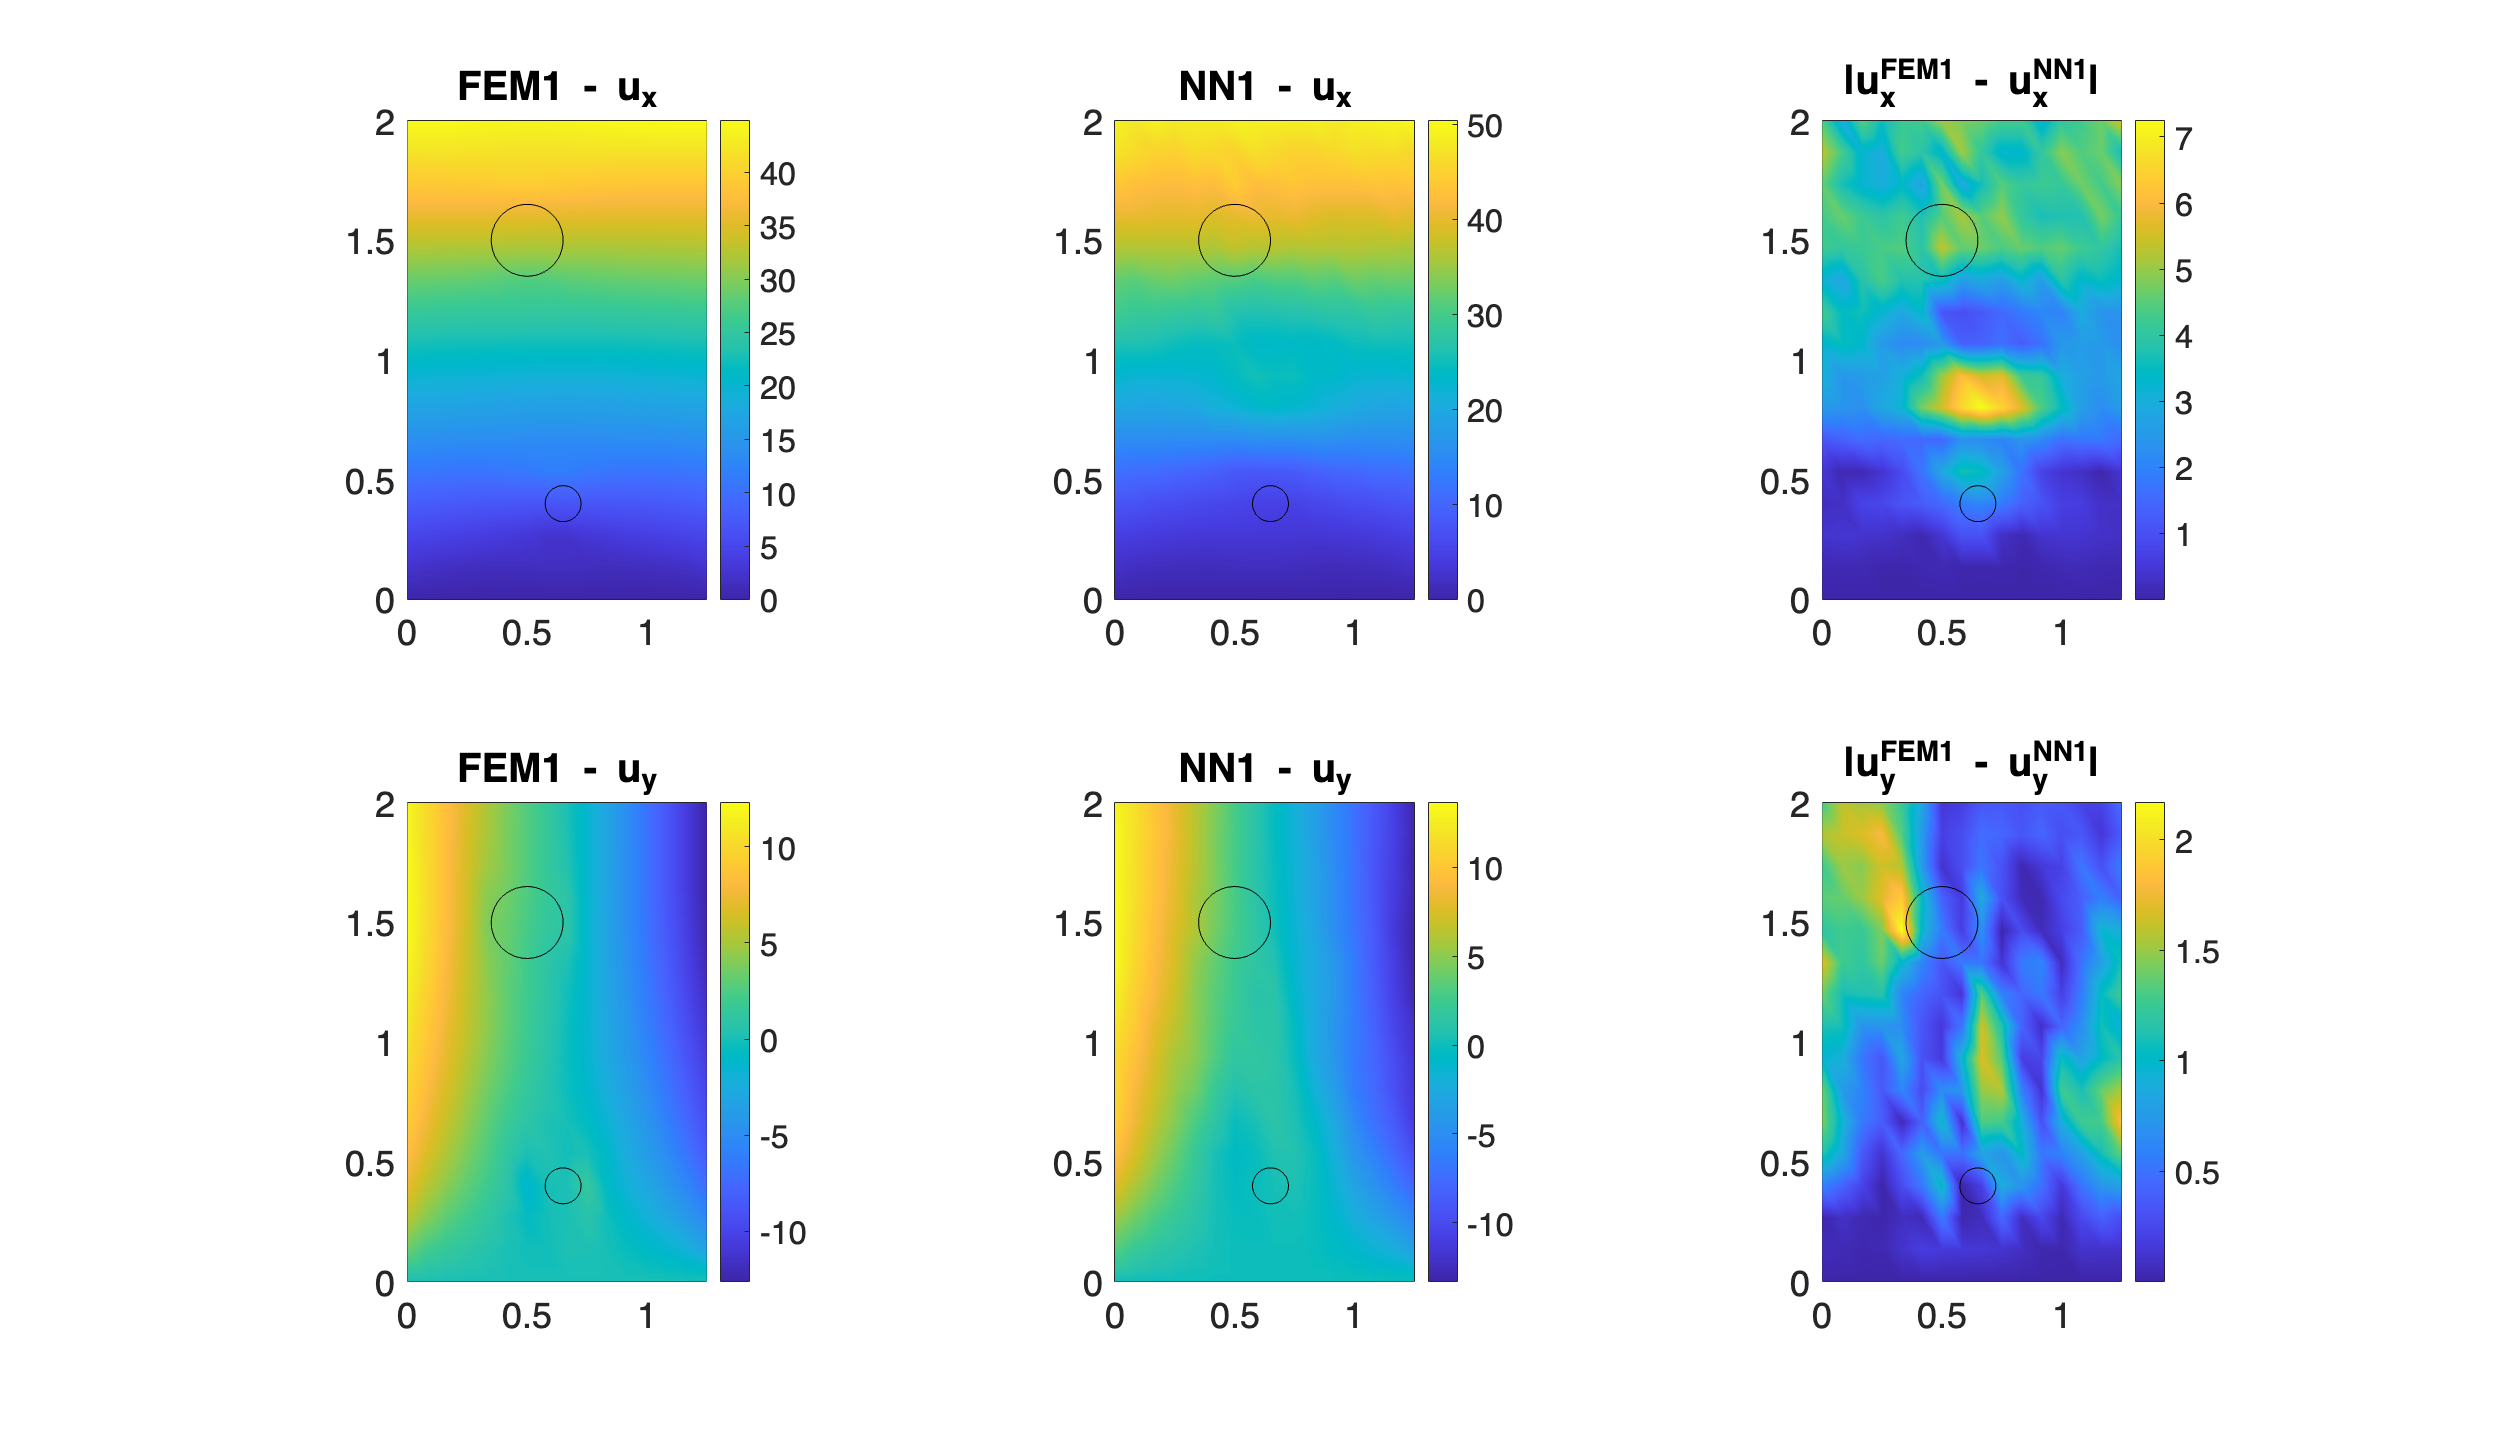

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF1); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('FEM1 - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN1); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('NN1 - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, abs(UxF1 - UxN1)); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('|u_x^{FEM1} - u_x^{NN1}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF1); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('FEM1 - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN1); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('NN1 - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, abs(UyF1 - UyN1)); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('|u_y^{FEM1} - u_y^{NN1}|');



%figures for NN2
fprintf('Figures for NN2 (body force y = %d):', bodyforcetesty(2))

Figures for NN2 (body force y = 3):

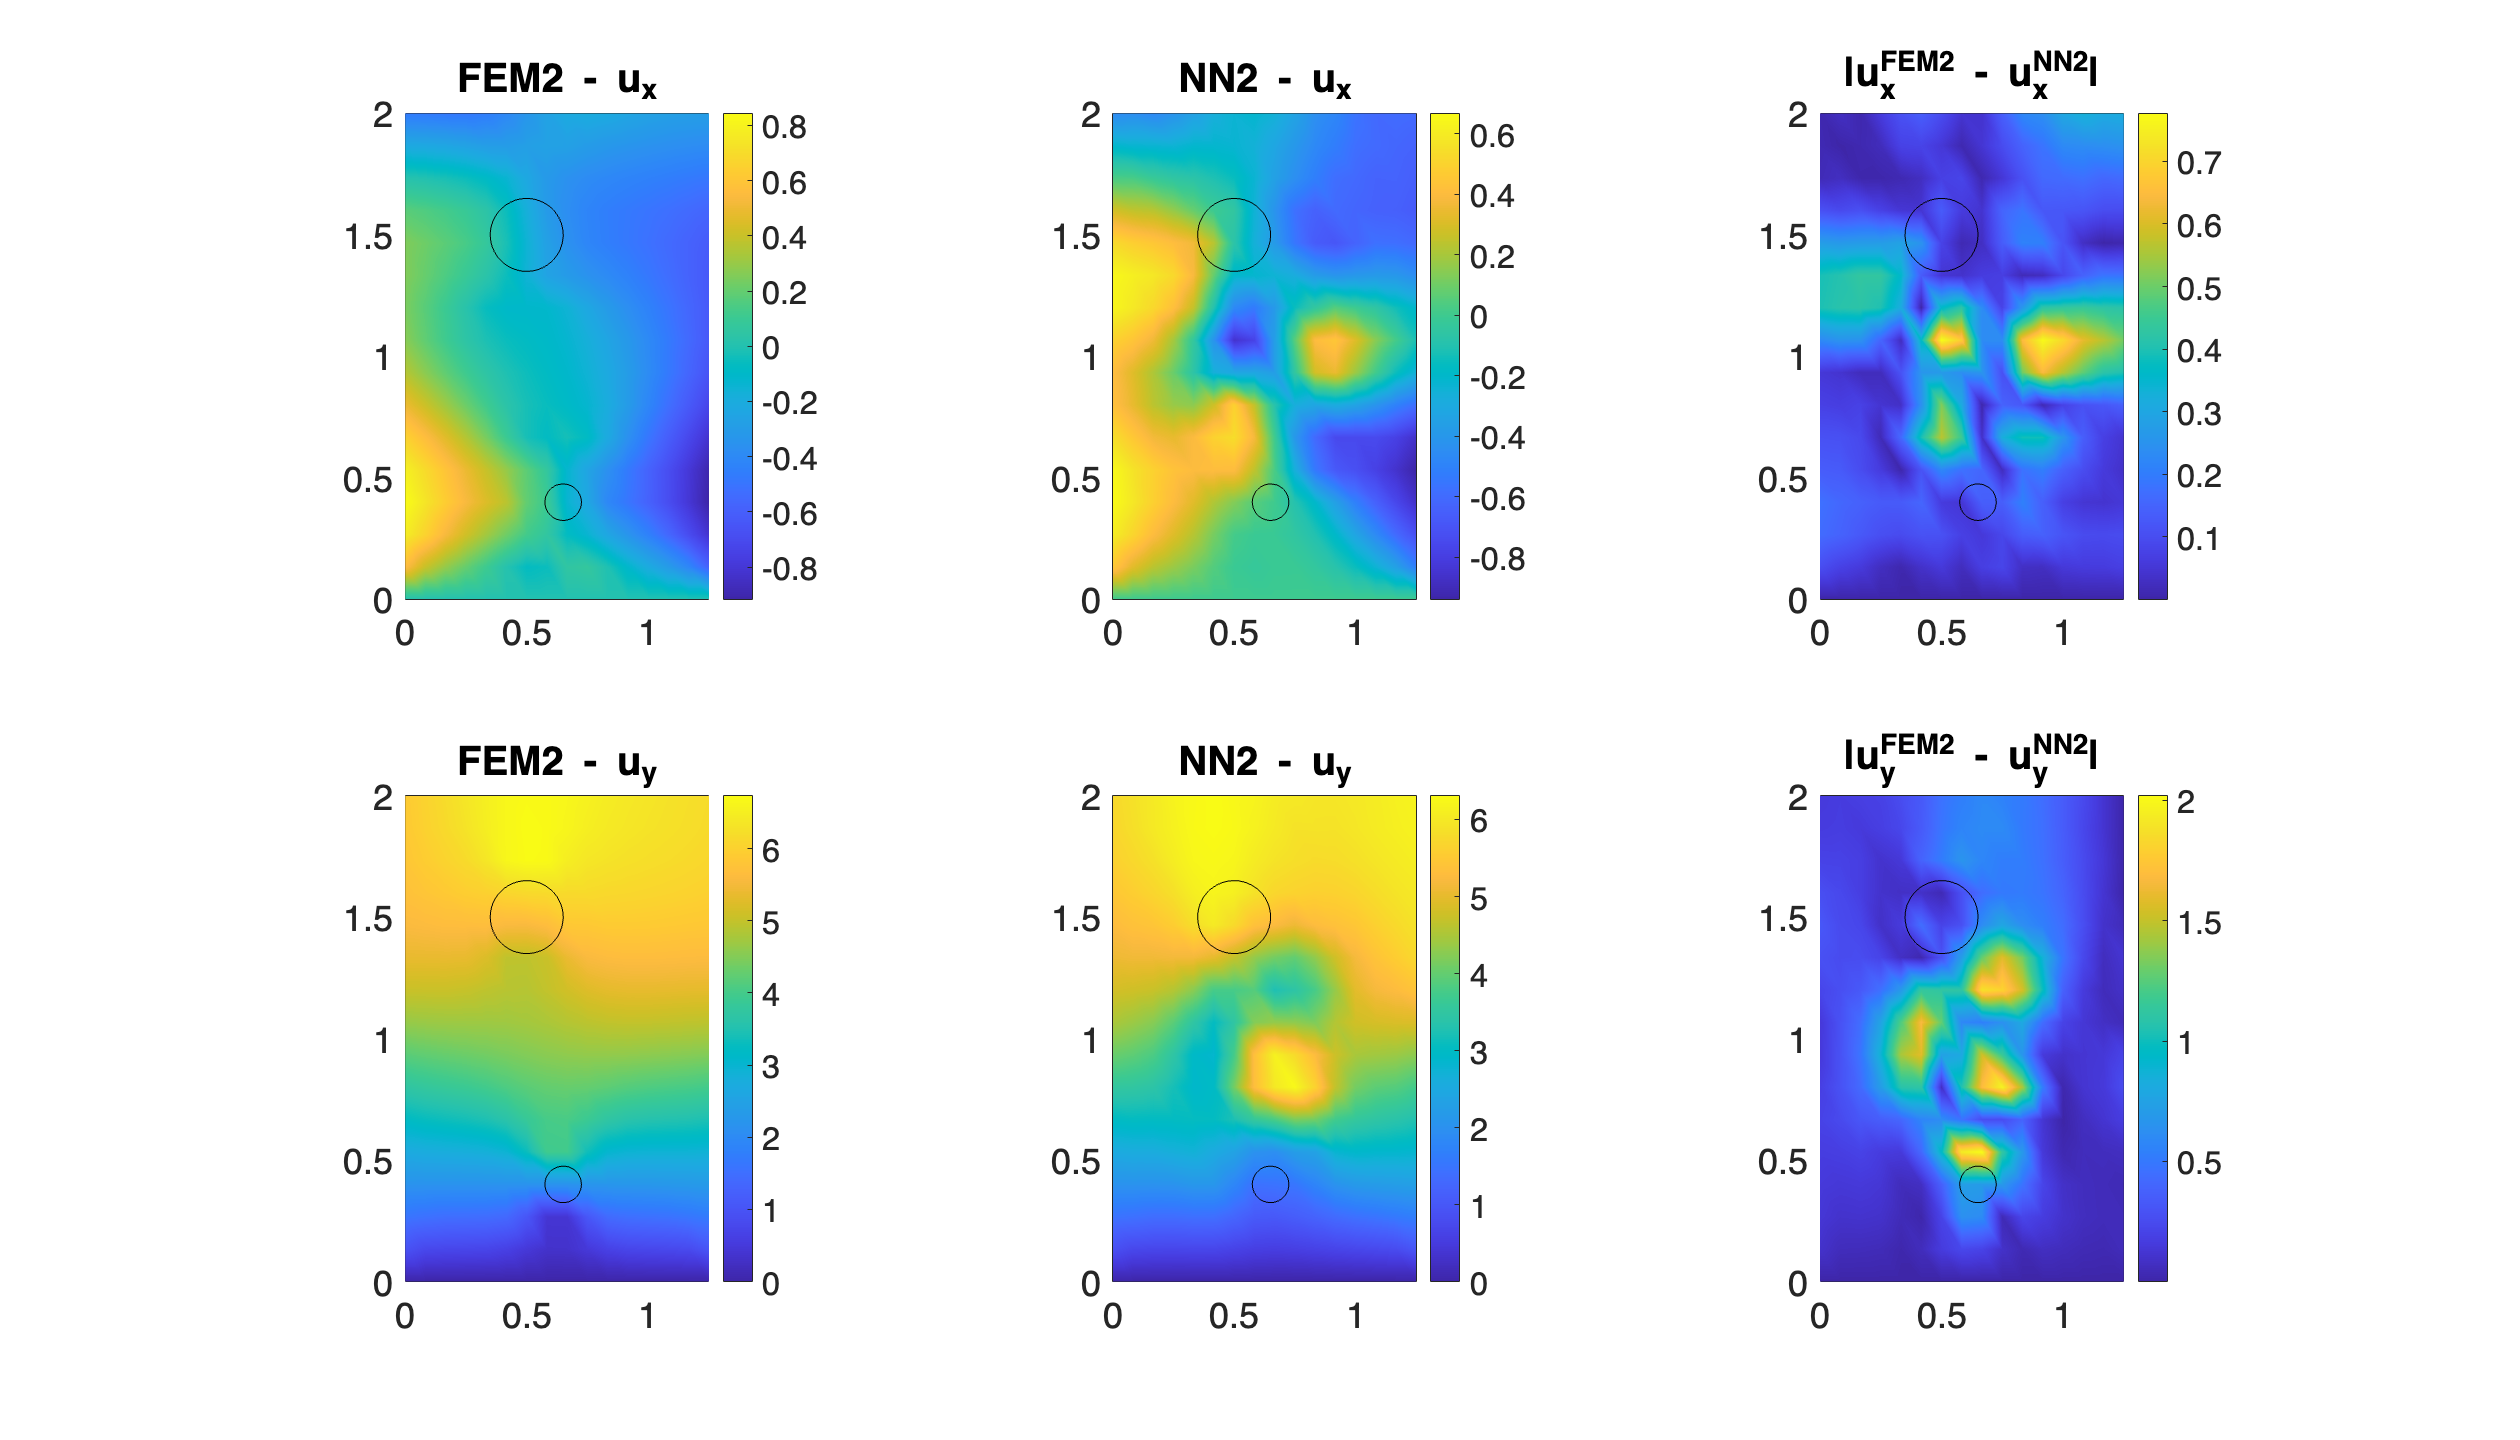

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF2); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('FEM2 - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN2); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('NN2 - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, abs(UxF2 - UxN2)); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('|u_x^{FEM2} - u_x^{NN2}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF2); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('FEM2 - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN2); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('NN2 - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, abs(UyF2 - UyN2)); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('|u_y^{FEM2} - u_y^{NN2}|');



%figures for combined disps
disp('Figures for combined displacements:')

Figures for combined displacements:


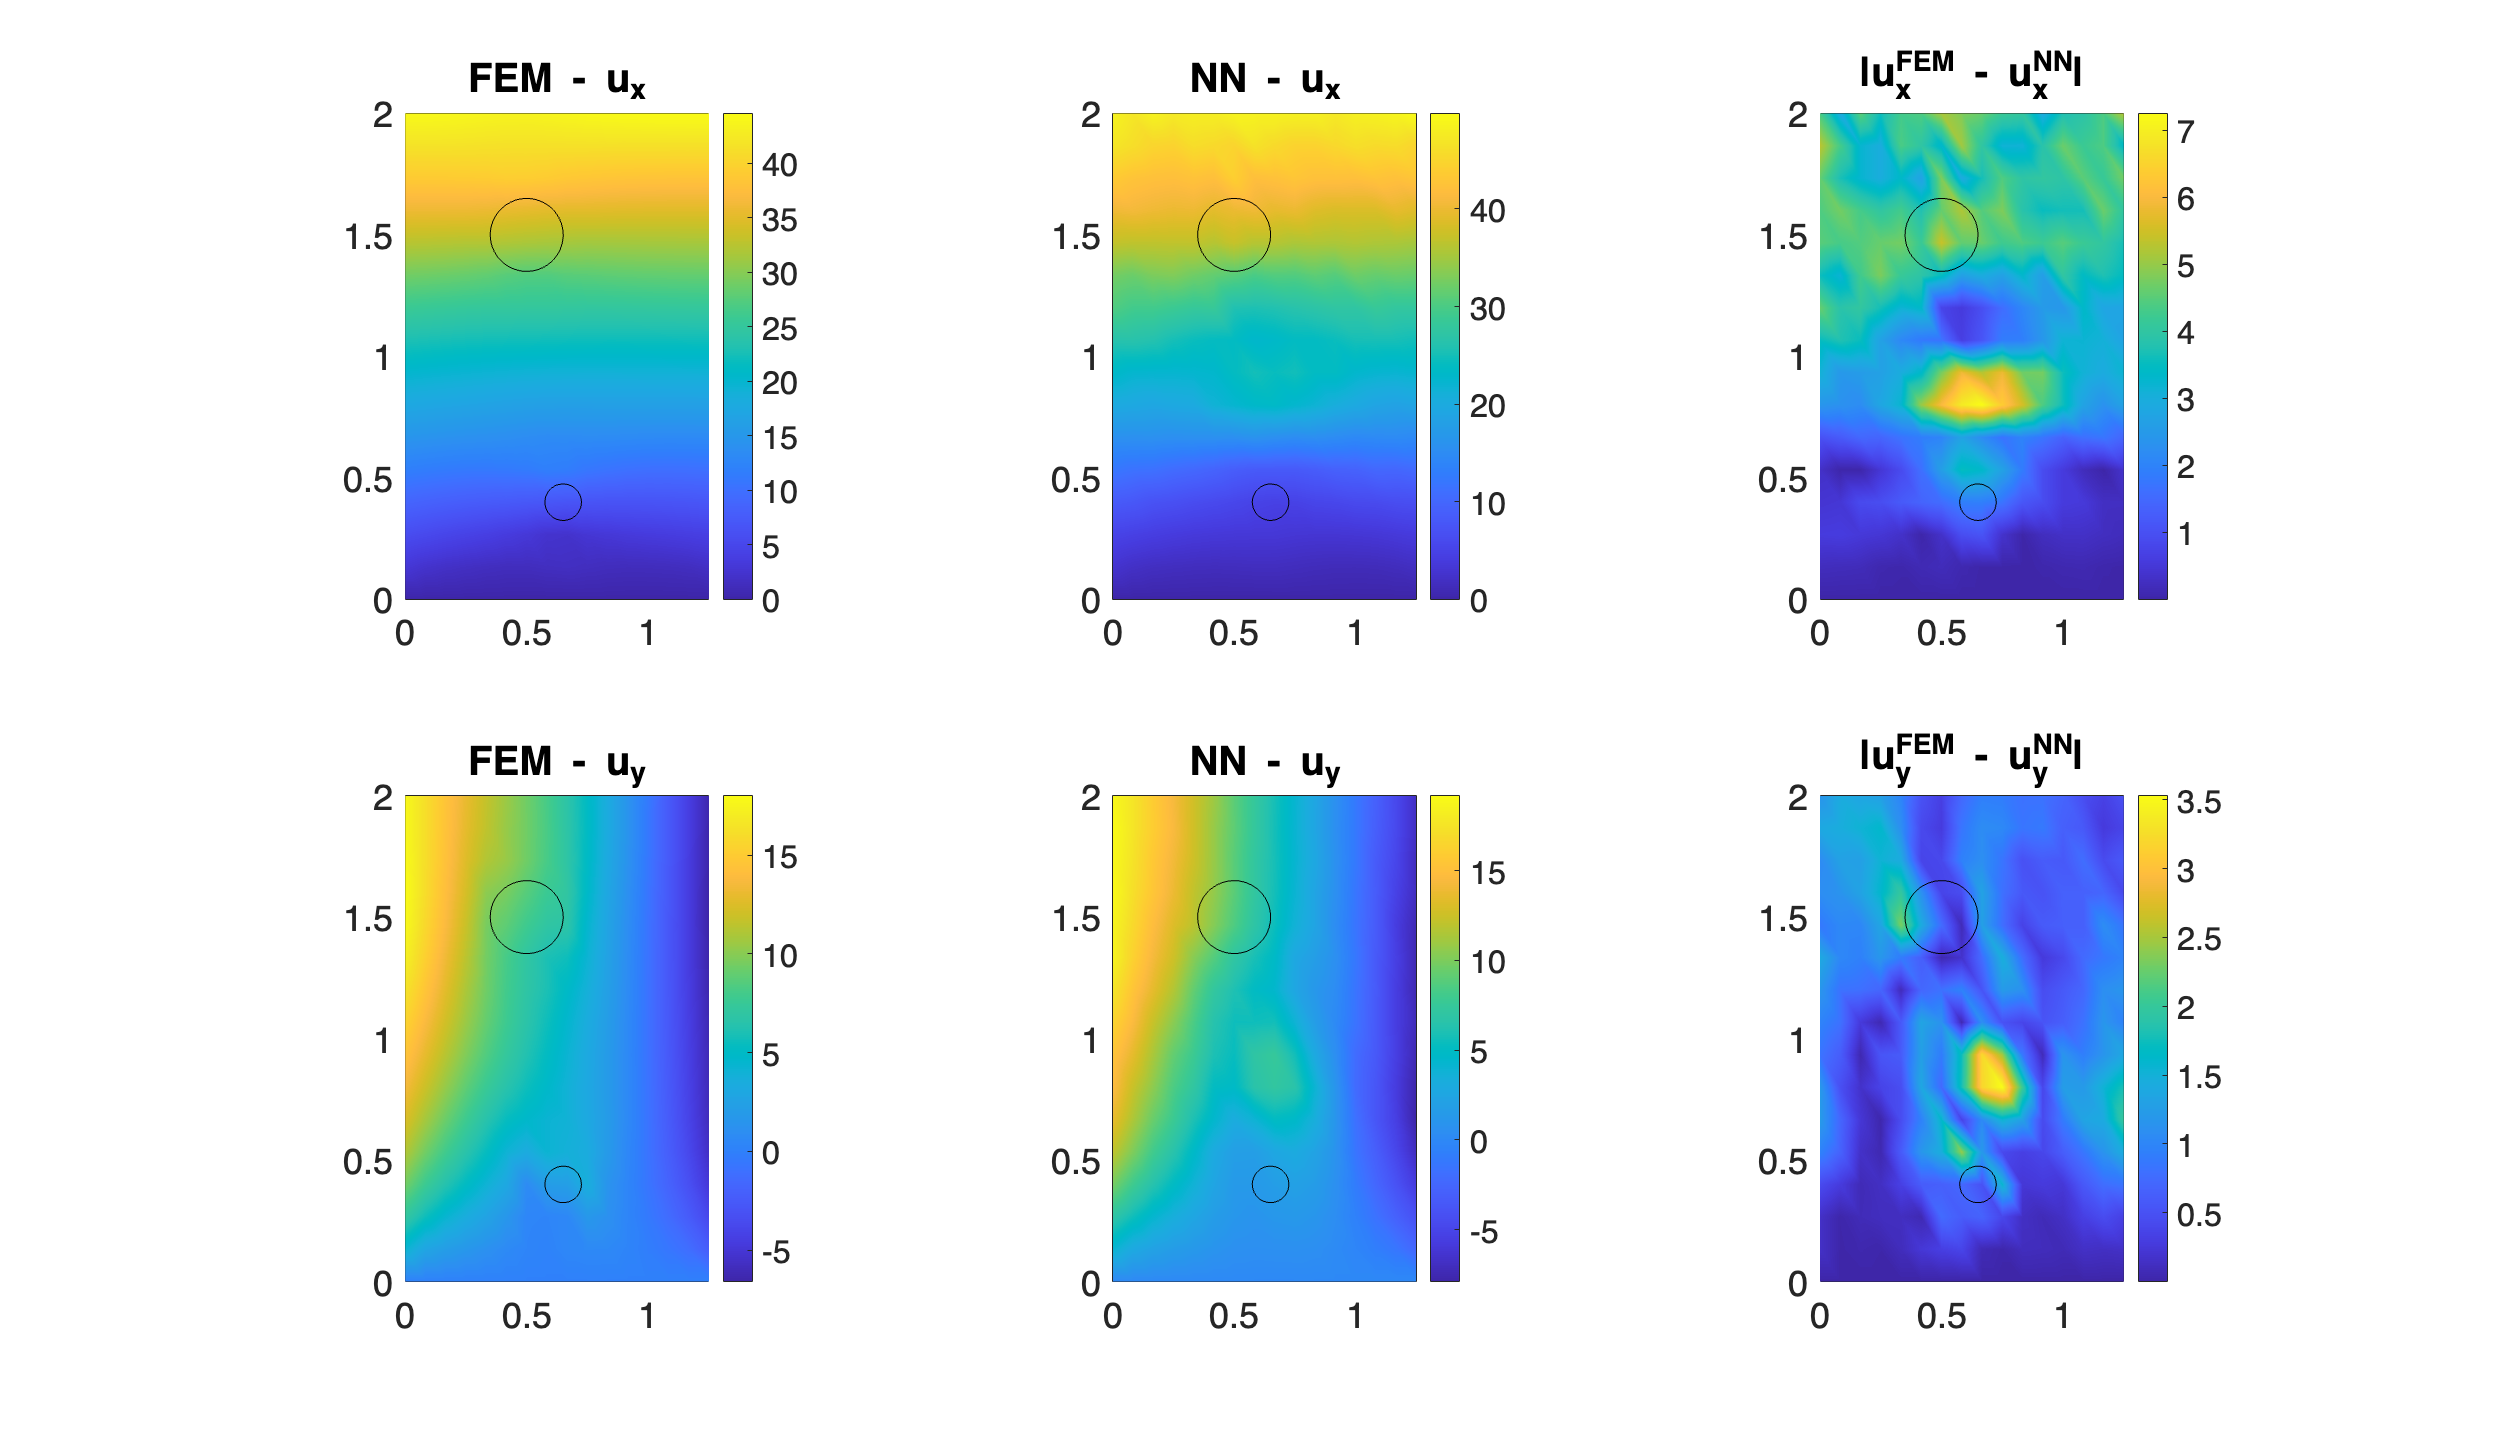

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('FEM - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('NN - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, Err_u); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('|u_x^{FEM} - u_x^{NN}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('FEM - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('NN - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, Err_v); shading interp; colorbar; axis equal tight;
overlayHole(cx1test, cy1test, dia1test/2);
overlayHole(cx2test, cy2test, dia2test/2);
title('|u_y^{FEM} - u_y^{NN}|');


% Errors 
u_FEM = u_FEM1 + u_FEM2;
u_NN  = u_NN1  + u_NN2;

err_vec = u_FEM - u_NN;
e = err_vec;
u_ref = u_FEM;

RMSE   = norm(e) / sqrt(numel(e));
relL2  = norm(e) / norm(u_ref);
maxErr = norm(e, Inf) / norm(u_ref, Inf);

fprintf('RMSE   : %.3e\n', RMSE);

RMSE   : 2.326e+00


fprintf('Relative L2 error : %.3e\n', relL2);

Relative L2 error : 1.243e-01


fprintf('Relative Infinity norm error: %.3e\n', maxErr);

Relative Infinity norm error: 1.628e-01



% % Errors for NN1 and NN2
% RMSE_1 = norm(u_FEM1 - u_NN1) / sqrt(numel(u_FEM1 - u_NN1));
% relL2_1 = norm(u_FEM1 - u_NN1) / norm(u_FEM1);
% maxErr_1 = norm(u_FEM1 - u_NN1, Inf) / norm(u_FEM1, Inf);
% 
% fprintf('RMSE (NN1)      : %.3e\n', RMSE_1);
% fprintf('Relative L2 error (NN1)  : %.3e\n', relL2_1);
% fprintf('Relative Infinity norm error (NN1)      : %.3e\n', maxErr_1); %maximum error
% 
% RMSE_2 = norm(u_FEM2 - u_NN2) / sqrt(numel(u_FEM2 - u_NN2));
% relL2_2 = norm(u_FEM2 - u_NN2) / norm(u_FEM2);
% maxErr_2 = norm(u_FEM2 - u_NN2, Inf) / norm(u_FEM2, Inf);
% 
% fprintf('RMSE (NN2)      : %.3e\n', RMSE_2);
% fprintf('Relative L2 error (NN2)  : %.3e\n', relL2_2);
% fprintf('Relative Infinity norm error (NN2)      : %.3e\n', maxErr_2); %maximum error

disp('✅ Verification completed.');

✅ Verification completed.


disp('For plotting:');

For plotting:


toc

Elapsed time is 3.673849 seconds.


%Generate Nodal Stresses via physics from NN1&2
sn_FEM = getNodalStresses(coords, nNodesX, nNodesY, E, E_hole, nu, u_FEM, cx1test, cy1test, dia1test, cx2test, cy2test, dia2test);
sn_NN  = getNodalStresses(coords, nNodesX, nNodesY, E, E_hole, nu, u_NN,  cx1test, cy1test, dia1test, cx2test, cy2test, dia2test);

% Reshape for plotting (nNodesY x nNodesX)
sx_F = reshape(sn_FEM(:,1), nNodesY, nNodesX);
sy_F = reshape(sn_FEM(:,2), nNodesY, nNodesX);
txy_F = reshape(sn_FEM(:,3), nNodesY, nNodesX);

sx_N = reshape(sn_NN(:,1), nNodesY, nNodesX);
sy_N = reshape(sn_NN(:,2), nNodesY, nNodesX);
txy_N = reshape(sn_NN(:,3), nNodesY, nNodesX);

%Nodal stresses via NN3
% nodestress_pred 192x1
sigma3_vec = nodestress_pred; % already denormalized

sigma3 = reshape(sigma3_vec, [3, nNodes])';

sx_NN3 = reshape(sigma3(:,1), nNodesY, nNodesX);
sy_NN3 = reshape(sigma3(:,2), nNodesY, nNodesX);
txy_NN3 = reshape(sigma3(:,3), nNodesY, nNodesX);

% --- Plotting ---
disp('Figures for stresses:')

Figures for stresses:


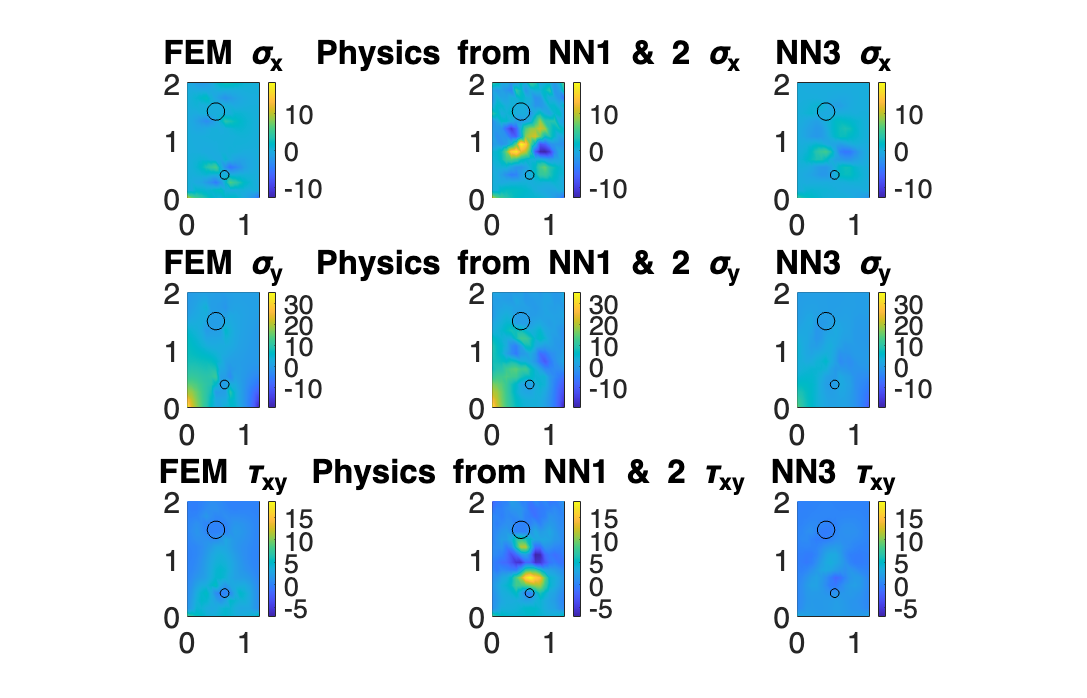

figure('Name', 'Smoothed Nodal Stresses', 'Position', [100 100 1400 900]);
titles = {'\sigma_x', '\sigma_y', '\tau_{xy}'};
data_F = {sx_F, sy_F, txy_F};
data_N = {sx_N, sy_N, txy_N};
data_NN3 = {sx_NN3, sy_NN3, txy_NN3};

for i = 1:3
    % 1. Determine shared limits for this specific stress component
    % We check both FEM and NN to find the absolute min/max
    combined_data = [data_F{i}(:); data_N{i}(:); data_NN3{i}(:)];
    clim_min = min(combined_data);
    clim_max = max(combined_data);
    
    % If min and max are identical (e.g., zero stress), offset them slightly to avoid errors
    if clim_min == clim_max
        clim_min = clim_min - 0.1;
        clim_max = clim_max + 0.1;
    end
    shared_lims = [clim_min, clim_max];

    % 2. Plot FEM
    subplot(3,3, (i-1)*3 + 1);
    pcolor(Xcoords, Ycoords, data_F{i}); 
    shading interp; colorbar; axis equal tight;
    clim(shared_lims); % Apply the shared scale
    overlayHole(cx1test, cy1test, dia1test/2);
    overlayHole(cx2test, cy2test, dia2test/2);
    title(['FEM ' titles{i}]);

    % 3. Plot physics-based from NN1 & 2
    subplot(3,3, (i-1)*3 + 2);
    pcolor(Xcoords, Ycoords, data_N{i}); 
    shading interp; colorbar; axis equal tight;
    clim(shared_lims); % Apply the EXACT SAME shared scale
    overlayHole(cx1test, cy1test, dia1test/2);
    overlayHole(cx2test, cy2test, dia2test/2);
    title(['Physics from NN1 & 2 ' titles{i}]);

    % % 4. Plot Absolute Error
    % subplot(3,3, (i-1)*3 + 3);
    % err_data = abs(data_F{i} - data_N{i});
    % pcolor(Xcoords, Ycoords, err_data); 
    % shading interp; colorbar; axis equal tight;
    % % Error plots usually keep their own scale (starting from 0) 
    % % to highlight where the NN is struggling most.
    % overlayHole(cxtest, cytest, diatest/2);
    % overlayHole(cx2test, cy2test, dia2test/2);
    % title(['|Error ' titles{i} '|']);

    % 4. Plot NN3
    subplot(3,3, (i-1)*3 + 3);
    pcolor(Xcoords, Ycoords, data_NN3{i}); 
    shading interp; colorbar; axis equal tight;
    clim(shared_lims); % Apply the EXACT SAME shared scale
    overlayHole(cx1test, cy1test, dia1test/2);
    overlayHole(cx2test, cy2test, dia2test/2);
    title(['NN3 ' titles{i}]);

end

===============================================================

Local functions

===============================================================


function [K,F] = buildPlaneStressFEM(coords,nx,ny,E,E_hole,nu,bodyForce,cx,cy,dia,cx2,cy2,dia2)
    % Structured mesh of 4-node bilinear quadrilateral elements
    nNodes = nx*ny;
    nElemX = nx-1; nElemY = ny-1;
    nElem = nElemX * nElemY;
    ndofNode = 2;
    nDOF = nNodes * ndofNode; %total dof of system

    % element connectivity matrix
    %(ix, iy) is one quadrilateral element
    conn = zeros(nElem,4);
    for ix = 1:nElemX
        for jy = 1:nElemY
            n1 = (ix-1)*ny + jy;
            n2 = ix*ny + jy;
            n3 = ix*ny + (jy+1);
            n4 = (ix-1)*ny + (jy+1);
            e = (ix-1)*nElemY + jy; %This converts the 2D element index (ix, jy) into a single element number
            conn(e,:) = [n1 n2 n3 n4]; %Element e connects nodes n1, n2, n3, n4
        end
    end

    K = zeros(nDOF);
    F = zeros(nDOF,1);

    % Plane stress constitutive matrix
    D = E / (1 - nu^2) * [1, nu, 0;
                          nu, 1, 0;
                          0, 0, (1-nu)/2];

    D_hole = E_hole / (1 - nu^2) * [1, nu, 0;
                          nu, 1, 0;...
                          0, 0, (1-nu)/2];

    % 2x2 Gauss
    gp = [-1/sqrt(3), 1/sqrt(3)];
    wgp = [1,1];

    for e = 1:nElem
        nodes = conn(e,:);
        xe = coords(nodes,1);
        ye = coords(nodes,2);

        elemCoords = coords(nodes, :);   % 4x2
        if elementInHole(elemCoords, cx, cy, dia/2) || elementInHole(elemCoords, cx2, cy2, dia2/2)
            D_elem = D_hole;
            bodyForce_elem = [0;0];   % no load in hole
        else
            D_elem = D;
            bodyForce_elem = bodyForce;
        end

        % if elementInHole(elemCoords, cx2, cy2, dia2/2)
        %     D_elem = D_hole;
        %     bodyForce_elem = [0;0];   % no load in hole
        % else
        %     D_elem = D;
        %     bodyForce_elem = bodyForce;
        % end

        %element stiffness and force matrix
        Ke = zeros(8,8);
        Fe = zeros(8,1);

        % Reduced integration term B0 for shear (as in original)
        xi = 0; eta = 0;
        [N0, dNdxi0, dNdeta0] = shape4(xi,eta);
        J0 = [dNdxi0'; dNdeta0'] * [xe, ye];
        detJ0 = det(J0);
        invJ0 = inv(J0);
        dN0 = [dNdxi0, dNdeta0] * invJ0;

        B0 = zeros(3,8);
        for a = 1:4
            dNx = dN0(a,1);
            dNy = dN0(a,2);
            col = (a-1)*2;
            B0(1, col + 1) = dNx;
            B0(2, col + 2) = dNy;
            B0(3, col + 1) = dNy;
            B0(3, col + 2) = dNx;
        end

        for i = 1:2
            for j = 1:2
                xi = gp(i); eta = gp(j);
                [N, dNdxi, dNdeta] = shape4(xi,eta);
                J = [dNdxi'; dNdeta'] * [xe, ye];
                detJ = det(J);

                % if detJ <= 0
                %     error('Element inverted or zero area element.');
                %     % error('Degenerate element detected.');
                %     continue
                % end

                invJ = inv(J);
                dN = [dNdxi, dNdeta] * invJ;

                B = zeros(3,8);
                for a = 1:4
                    dNx = dN(a,1);
                    dNy = dN(a,2);
                    col = (a-1)*2;
                    B(1, col + 1) = dNx;
                    B(2, col + 2) = dNy;
                    B(3, col + 1) = dNy;
                    B(3, col + 2) = dNx;
                end

                % replace shear row with reduced B0 shear row
                B(3,:) = B0(3,:);

                Ke = Ke + (B' * D_elem * B) * detJ * wgp(i) * wgp(j);

                Nmat = zeros(2,8);
                for a = 1:4
                    Nmat(1, (a-1)*2 + 1) = N(a);
                    Nmat(2, (a-1)*2 + 2) = N(a);
                end
                Fe = Fe + (Nmat' * bodyForce_elem) * detJ * wgp(i) * wgp(j);
            end
        end

        % assemble
        gdofs = zeros(8,1);
        for a = 1:4
            node = nodes(a);
            gdofs((a-1)*2 + (1:2)) = (node-1)*2 + (1:2);
        end
        K(gdofs, gdofs) = K(gdofs, gdofs) + Ke;
        F(gdofs) = F(gdofs) + Fe;
    end
end

function [N, dNdxi, dNdeta] = shape4(xi,eta)
    N = 0.25*[(1-xi)*(1-eta);
              (1+xi)*(1-eta);
              (1+xi)*(1+eta);
              (1-xi)*(1+eta)];
    dNdxi  = 0.25*[-(1-eta); (1-eta); (1+eta); -(1+eta)];
    dNdeta = 0.25*[-(1-xi); -(1+xi); (1+xi);  (1-xi)];
end

function [loss,gradients] = modelLoss(dlnet,X,Y)
    % Simple MSE loss for single network
    Ypred = forward(dlnet,X);
    loss = mean((Ypred - Y).^2,'all');
    gradients = dlgradient(loss, dlnet.Learnables);
end

%check if the element lies in the hole
% function isInside = elementInHole(elemCoords, cx, cy, radius)
%     % elemCoords: 4x2 matrix of node coordinates for one quad element
%     % Returns true if element centroid falls inside the circular hole
%     centroid = mean(elemCoords, 1);   % [cx_elem, cy_elem]
%     %computes the average of the 4 node coordinates of one element giving the centroid of that element
%     dist = sqrt((centroid(1)-cx)^2 + (centroid(2)-cy)^2);
%     isInside = dist < radius;
% end
function isInside = elementInHole(elemCoords, cx, cy, radius)
    distances = sqrt((elemCoords(:,1)-cx).^2 + (elemCoords(:,2)-cy).^2);
    
    % Option 1: ANY node inside → element is hole
    isInside = any(distances < radius);

    % Option 2 (stricter): ALL nodes inside → element is hole
    % isInside = all(distances < radius);
end

function overlayHole(cx, cy, r)
theta = linspace(0, 2*pi, 100);
xc = cx + r*cos(theta);
yc = cy + r*sin(theta);
hold on;
% fill(xc, yc, 'w');
h = plot(xc, yc, 'Color','k');
hold off;
end

% %stresses at gauss points
% function [sigma_x, sigma_y, tau_xy] = computeStresses(coords,nx,ny,E,E_hole,nu,u,cx,cy,dia)
% nElemX = nx-1;
% nElemY = ny-1;
% nElem  = nElemX*nElemY;
% 
% % plane stress matrix
% D = (E/(1-nu^2))*[1 nu 0;
%                 nu 1 0;
%                 0  0 (1-nu)/2];
% 
% D_hole = (E_hole / (1 - nu^2)) * [1, nu, 0;
%     nu, 1, 0;...
%     0, 0, (1-nu)/2];
% 
% sigma_x  = zeros(nElem,4);
% sigma_y  = zeros(nElem,4);
% tau_xy = zeros(nElem,4);
% 
% gp = [-1/sqrt(3) 1/sqrt(3)];
% 
% elem = 0;
% 
% for ix = 1:nElemX
% for iy = 1:nElemY
% 
%     elem = elem + 1;
% 
%     n1 = (ix-1)*ny + iy;
%     n2 = ix*ny + iy;
%     n3 = ix*ny + (iy+1);
%     n4 = (ix-1)*ny + (iy+1);
% 
%     nodes = [n1 n2 n3 n4];
% 
%     %extract element coordinates
%     xe = coords(nodes,1);
%     ye = coords(nodes,2);
% 
%     elemCoords = coords(nodes, :);   % 4x2
%     if elementInHole(elemCoords, cx, cy, dia/2)
%         D_elem = D_hole;
%     else
%         D_elem = D;
%     end
% 
%     %extract element displacement vector
%     ue = zeros(8,1);
%     for a=1:4 %4nodes
%         node = nodes(a);
%         ue((a-1)*2+1:(a-1)*2+2) = u((node-1)*2+1:(node-1)*2+2);
%     end
% 
%     gpcount = 0;
% 
%     %loops through 4 gauss points
%     for i=1:2
%     for j=1:2
% 
%         %gauss point coordinates
%         xi  = gp(i);
%         eta = gp(j);
%         gpcount = gpcount + 1;
%         [N,dNdxi,dNdeta] = shape4(xi,eta);
%         J = [dNdxi'; dNdeta'] * [xe ye];
%         invJ = inv(J);
%         dN = [dNdxi dNdeta] * invJ;
% 
%         B = zeros(3,8);
%         for a=1:4
%             dNx = dN(a,1);
%             dNy = dN(a,2);
%             col = (a-1)*2;
%             B(1,col+1) = dNx;
%             B(2,col+2) = dNy;
%             B(3,col+1) = dNy;
%             B(3,col+2) = dNx;
%         end
% 
%         strain = B*ue;
%         stress = D_elem*strain;
% 
%         %Each element stores 4 stress values, one per Gauss point.
%         sigma_x(elem,gpcount)  = stress(1);
%         sigma_y(elem,gpcount)  = stress(2);
%         tau_xy(elem,gpcount) = stress(3);
%     end
%     end
% end
% end
% end

%stresses at nodes -
%gauss point stresses projected at nodes, averaged from all elements sharing that node
function [s_node] = getNodalStresses(coords, nx, ny, E, E_hole, nu, u, cx, cy, dia, cx2, cy2, dia2)
    nNodes = nx * ny;
    nElemX = nx - 1; nElemY = ny - 1;
    
    % Initialize accumulators
    s_node = zeros(nNodes, 3); % [sigma_x, sigma_y, tau_xy]
    node_count = zeros(nNodes, 1);
    
    % Extrapolation points (the nodes in natural coordinates)
    % For a quad element, nodes are at (-1,-1), (1,-1), (1,1), (-1,1)
    node_local = [-1 -1; 1 -1; 1 1; -1 1];
    
    % Constitutive matrices
    D = (E/(1-nu^2)) * [1 nu 0; nu 1 0; 0 0 (1-nu)/2];
    D_hole = (E_hole/(1-nu^2)) * [1 nu 0; nu 1 0; 0 0 (1-nu)/2];

    for ix = 1:nElemX
        for iy = 1:nElemY
            % Element Connectivity
            n1 = (ix-1)*ny + iy; n2 = ix*ny + iy;
            n3 = ix*ny + (iy+1); n4 = (ix-1)*ny + (iy+1);
            nodes = [n1 n2 n3 n4];
            
            xe = coords(nodes, 1); ye = coords(nodes, 2);
            ue = reshape(u([(nodes-1)*2+1; (nodes-1)*2+2]), [], 1);
            
            % Hole or plate check
            % centroid = mean(coords(nodes,:), 1);
            % if sqrt((centroid(1)-cx)^2 + (centroid(2)-cy)^2) < dia/2 
            %     D_elem = D_hole;
            % else
            %     D_elem = D;
            % end
            elemCoords = coords(nodes, :);   % 4x2
            if elementInHole(elemCoords, cx, cy, dia/2) || elementInHole(elemCoords, cx2, cy2, dia2/2)
                D_elem = D_hole;
                % bodyForce_elem = [0;0];   % no load in hole
            else
                D_elem = D;
                % bodyForce_elem = bodyForce;
            end

            % For each node of the element, calculate stress
            for a = 1:4
                xi = node_local(a,1); eta = node_local(a,2);
                [~, dNdxi, dNdeta] = shape4(xi, eta);
                J = [dNdxi'; dNdeta'] * [xe ye];
                dN = [dNdxi dNdeta] * inv(J);
                
                B = zeros(3,8);
                for i = 1:4
                    B(1, (i-1)*2+1) = dN(i,1);
                    B(2, (i-1)*2+2) = dN(i,2);
                    B(3, (i-1)*2+1) = dN(i,2);
                    B(3, (i-1)*2+2) = dN(i,1);
                end
                
                stress = D_elem * B * ue;
                s_node(nodes(a), :) = s_node(nodes(a), :) + stress';
                node_count(nodes(a)) = node_count(nodes(a)) + 1;
            end
        end
    end
    % Average by number of elements sharing the node
    s_node = s_node ./ node_count;
end


